Loading in the data

phRf1 = load("phantomRFdata1.mat");
phRf2 = load("phantomRFdata2.mat");
caRf = load("cardiacRFdata.mat");

Assigning the information gained above

Rf1 = phRf1.rf;
Rf2 = phRf2.rf;
cardRf = caRf.rf;
[Rf1_rows,Rf1_cols] = size(Rf1);
[Rf2_rows,Rf2_cols] = size(Rf2);
[card_rows,card_cols] = size(cardRf);
cardRf_f0 = caRf.p.f0_Hz;
cardRf_start_angle = caRf.p.startangle_rad;
cardRf_start_depth = caRf.p.startdepth_m;
Rf1_f0 = phRf1.p.f0_Hz;
Rf2_f0 = phRf2.p.f0_Hz;
Rf1_start_angle = phRf1.p.startangle_rad;
Rf2_start_angle = phRf2.p.startangle_rad;
Rf1_start_depth = phRf1.p.startdepth_m;
Rf2_start_depth = phRf2.p.startdepth_m;
Rf1_angle_inc = phRf1.p.angleincrement_rad;
Rf2_angle_inc = phRf2.p.angleincrement_rad;
cardRf_angle_inc = caRf.p.angleincrement_rad;
cardRf_frs = caRf.p.frs_Hz;
Rf1_frs = phRf1.p.frs_Hz;
Rf2_frs = phRf2.p.frs_Hz;

Plotting the signals for useful information

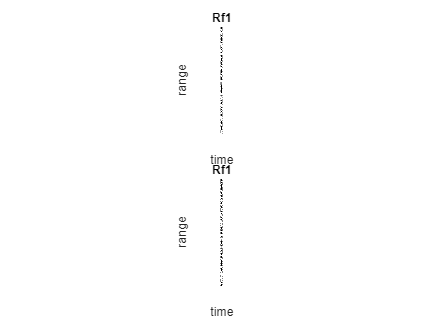

t1_axis = (0:1/Rf1_frs:(Rf1_rows*1/Rf1_frs)-1/Rf1_frs).';
t3_axis = (0:1/cardRf_frs:(card_rows*1/cardRf_frs)-1/cardRf_frs).';
t4_axis = (0:1/(cardRf_frs*2):(card_rows*1/(cardRf_frs*2))-1/(cardRf_frs*2)).';
figure(1);
subplot(2,1,1);
imshow(Rf1);
title("Rf1");
xlabel("time");
ylabel("range");
t2_axis = (0:1/Rf2_frs:(Rf2_rows*1/Rf2_frs)-1/Rf2_frs).';
subplot(2,1,2);
imshow(Rf2);
title("Rf1");
xlabel("time");
ylabel("range");

%remembered now that these are images and not useful to plot like this%changed to imshow


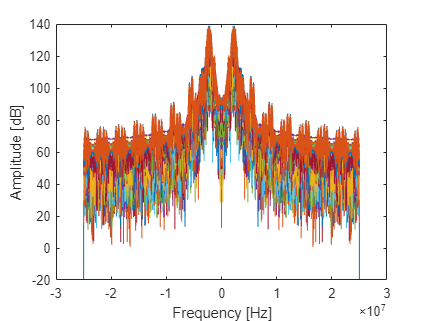

Nfft1 = length(t1_axis);
f1axis = linspace(-0.5,0.5-1/Nfft1,Nfft1)*Rf1_frs;
figure(2);
plot(f1axis,fftshift(20*log10(abs(fft(Rf1,Nfft1)))));
xlabel("Frequency [Hz]");
ylabel("Amplitude [dB]");

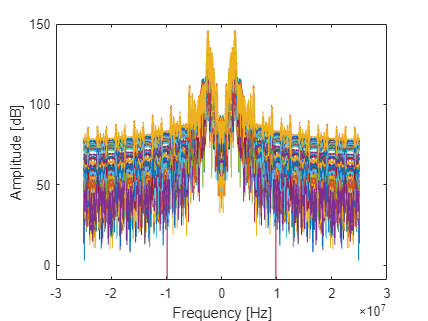


figure(3)
Nfft2 = length(t2_axis);
f2axis = linspace(-0.5,0.5-1/Nfft2,Nfft2)*Rf2_frs;
plot(f2axis,fftshift(20*log10(abs(fft(Rf2,Nfft2)))));
xlabel("Frequency [Hz]");
ylabel("Amplitude [dB]");

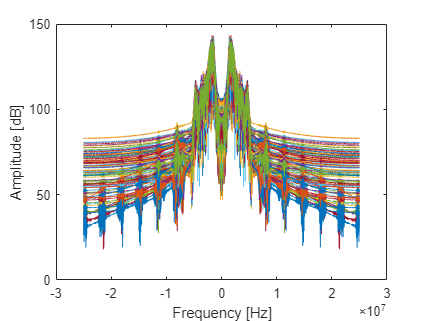


figure(12)
Nfft3 = length(t3_axis);
f3axis = linspace(-0.5,0.5-1/Nfft3,Nfft3)*cardRf_frs;
plot(f3axis,fftshift(20*log10(abs(fft(cardRf,Nfft3)))));
xlabel("Frequency [Hz]");
ylabel("Amplitude [dB]");

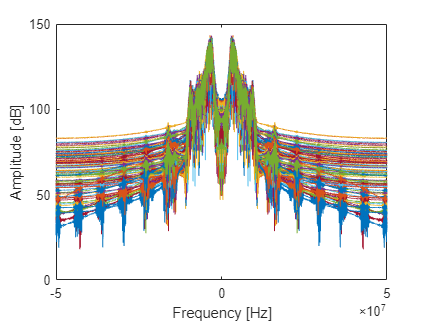


figure(17)
Nfft4 = length(t4_axis);
f4axis = linspace(-0.5,0.5-1/Nfft4,Nfft4)*cardRf_frs*2;
plot(f4axis,fftshift(20*log10(abs(fft(cardRf,Nfft4)))));
xlabel("Frequency [Hz]");
ylabel("Amplitude [dB]");

Task 1 a

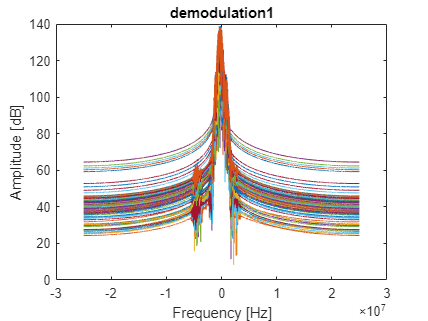


figure(4);
demod1 = demodulation("phantomRFdata1.mat",1e6);
plot(f1axis,fftshift(20*log10(abs(fft(demod1,Nfft1)))));
title("demodulation1");
xlabel("Frequency [Hz]");
ylabel("Amplitude [dB]");

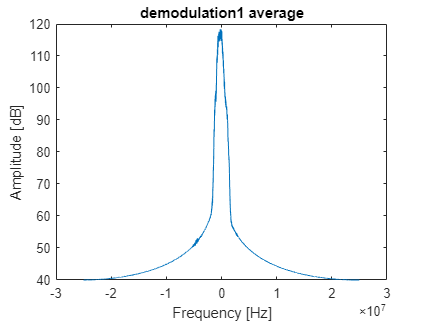

figure(5);
plot(f1axis,mean(fftshift(20*log10(abs(fft(demod1,Nfft1)))),2));
title("demodulation1 average");
xlabel("Frequency [Hz]");
ylabel("Amplitude [dB]");

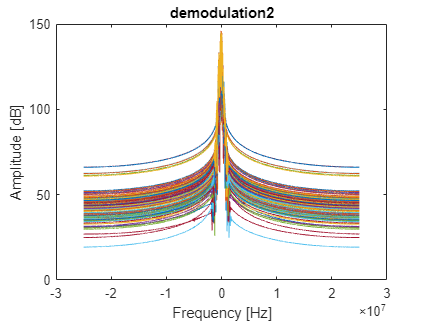


figure(6);
demod2 = demodulation("phantomRFdata2.mat",0.5e6); %didnt see any change before 0.5 from 1e6
plot(f2axis,fftshift(20*log10(abs(fft(demod2,Nfft2)))));
title("demodulation2");
xlabel("Frequency [Hz]");
ylabel("Amplitude [dB]");

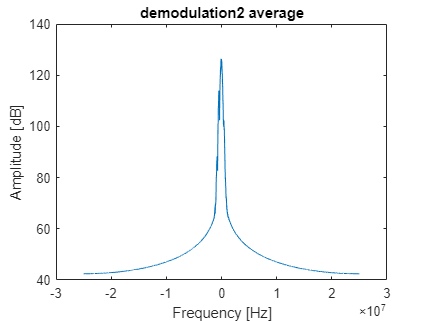

figure(7);
plot(f2axis,mean(fftshift(20*log10(abs(fft(demod2,Nfft2)))),2));
title("demodulation2 average");
xlabel("Frequency [Hz]");
ylabel("Amplitude [dB]");

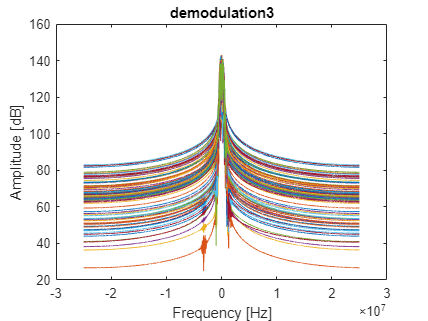


figure(13);
demod3 = demodulation("cardiacRFdata.mat",0.5e6); %didnt see any change before 0.5 from 1e6
plot(f3axis,fftshift(20*log10(abs(fft(demod3,Nfft3)))));
title("demodulation3");
xlabel("Frequency [Hz]");
ylabel("Amplitude [dB]");

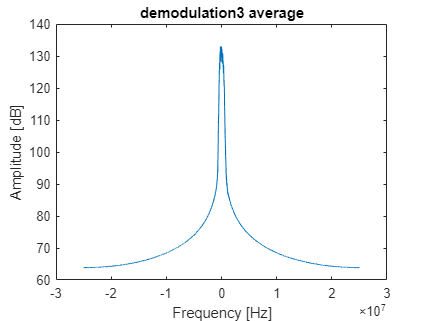

figure(14);
plot(f3axis,mean(fftshift(20*log10(abs(fft(demod3,Nfft3)))),2));
title("demodulation3 average");
xlabel("Frequency [Hz]");
ylabel("Amplitude [dB]");

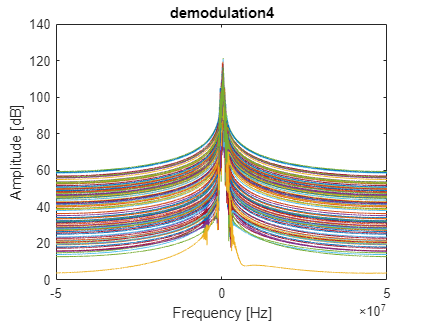



figure(13);
demod4 = demodulation2("cardiacRFdata.mat",0.5e6); %didnt see any change before 0.5 from 1e6
plot(f4axis,fftshift(20*log10(abs(fft(demod4,Nfft4)))));
title("demodulation4");
xlabel("Frequency [Hz]");
ylabel("Amplitude [dB]");

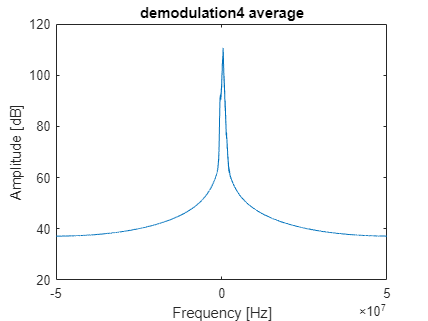

figure(14);
plot(f4axis,mean(fftshift(20*log10(abs(fft(demod4,Nfft4)))),2));
title("demodulation4 average");
xlabel("Frequency [Hz]");
ylabel("Amplitude [dB]");

Task 2

c = 1540;
%depth1_axis2 = linspace(Rf1_start_depth, Rf1_start_depth+c*t1_axis*Rf1_rows, Rf1_rows);
depth1_axis = t1_axis*c/2 + Rf1_start_depth;
depth2_axis = t2_axis*c/2 + Rf2_start_depth;
depth3_axis = t3_axis*c/2 + cardRf_start_depth;
depth4_axis = t4_axis*c/2 + cardRf_start_depth;
midline1 = Rf1(:,Rf1_cols/2);
midline2 = Rf2(:,Rf2_cols/2);
midline3 = cardRf(:,card_cols/2)

midline3 = 	1.0e+04 *

    0.1782
    0.0563
   -0.0181
   -0.0706
   -0.1221
   -0.1849
   -0.2618
   -0.3472
   -0.4292
   -0.4939


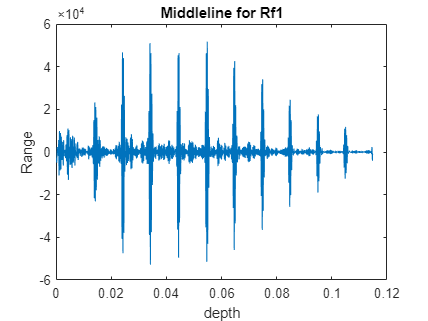


figure(7);
plot(depth1_axis,midline1);
title("Middleline for Rf1");
xlabel("depth");
ylabel("Range");

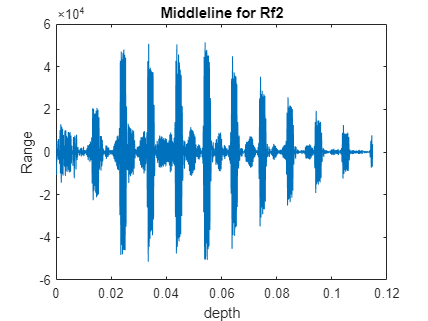

figure(8);
plot(depth2_axis,midline2);
title("Middleline for Rf2");
xlabel("depth");
ylabel("Range");

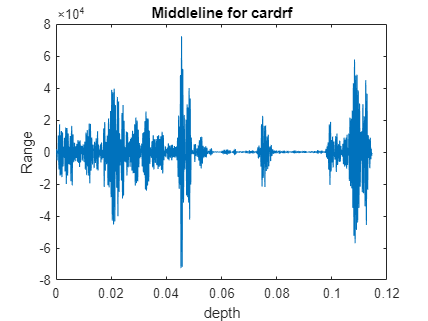


figure(15);
plot(depth3_axis,midline3);
title("Middleline for cardrf");
xlabel("depth");
ylabel("Range");

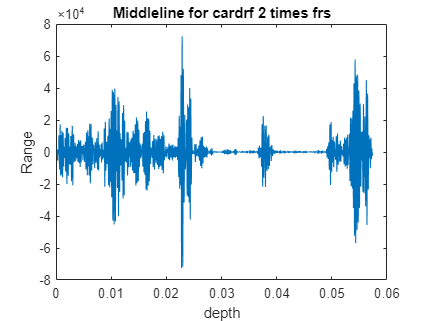


figure(18);
plot(depth4_axis,midline3);
title("Middleline for cardrf 2 times frs");
xlabel("depth");
ylabel("Range");

env1_f = envelope(Rf1); %dont know if this gives the same result as the one under
env1 = abs(conj(Rf1))*2

env1 = 	1.0e+05 *

    0.0251    0.0214    0.0096    0.0055    0.0054    0.0083    0.0023    0.0004    0.0061    0.0038    0.0069    0.0037    0.0094    0.0069    0.0046    0.0056    0.0073    0.0048    0.0141    0.0110    0.0143    0.0113    0.0190    0.0171    0.0180    0.0154    0.0144    0.0119    0.0100    0.0077    0.0114    0.0091    0.0319    0.0298    0.0252    0.0238    0.0267    0.0349    0.0151    0.0128    0.0287    0.0256    0.0152    0.0150    0.0127    0.0198    0.0088    0.0055    0.0121    0.0088
    0.0271    0.0224    0.0123    0.0065    0.0004    0.0038    0.0073    0.0027    0.0102    0.0059    0.0103    0.0052    0.0118    0.0078    0.0070    0.0065    0.0094    0.0050    0.0172    0.0127    0.0182    0.0137    0.0222    0.0188    0.0213    0.0171    0.0184    0.0143    0.0141    0.0100    0.0145    0.0107    0.0371    0.0336    0.0320    0.0292    0.0339    0.0393    0.0216    0.0178    0.0348    0.0302    0.0206    0.0173    0.0186    0.0221    0.0070    0.0016

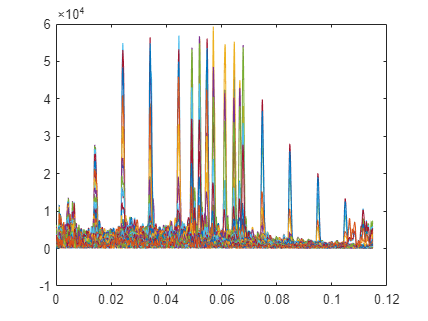

figure(9);
plot(depth1_axis, env1_f);

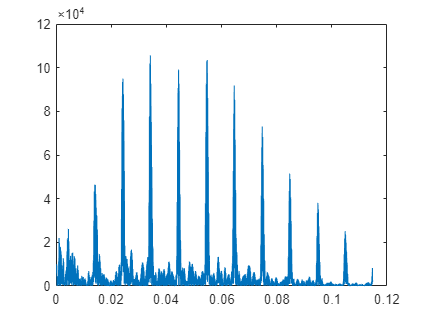

figure(10);
plot(depth1_axis, env1(:,Rf1_cols/2));


env2 = abs(conj(Rf2))*2

env2 = 	1.0e+05 *

    0.0286    0.0288    0.0318    0.0328    0.0217    0.0220    0.0206    0.0195    0.0111    0.0109    0.0075    0.0100    0.0065    0.0078    0.0120    0.0122    0.0052    0.0057    0.0046    0.0065    0.0094    0.0087    0.0055    0.0049    0.0171    0.0167    0.0104    0.0097    0.0031    0.0038    0.0052    0.0142    0.0142    0.0122    0.0387    0.0386    0.0385    0.0425    0.0541    0.0565    0.0672    0.0715    0.0760    0.0801    0.0955    0.1068    0.1100    0.1127    0.1339    0.1372
    0.0215    0.0218    0.0238    0.0252    0.0153    0.0159    0.0167    0.0153    0.0097    0.0091    0.0075    0.0098    0.0073    0.0085    0.0104    0.0107    0.0057    0.0057    0.0051    0.0067    0.0071    0.0069    0.0036    0.0031    0.0154    0.0156    0.0105    0.0101    0.0049    0.0061    0.0099    0.0176    0.0189    0.0172    0.0418    0.0422    0.0425    0.0494    0.0620    0.0645    0.0755    0.0799    0.0846    0.0888    0.1029    0.1118    0.1154    0.1174

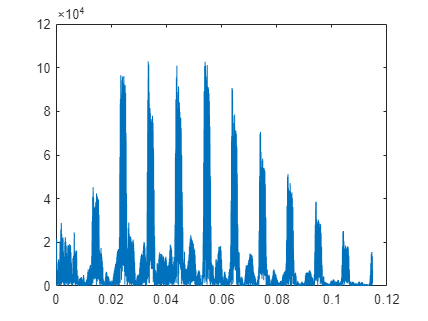

figure(11);
plot(depth2_axis, env2(:,Rf2_cols/2));


env3 = abs(conj(cardRf))*2

env3 = 	1.0e+05 *

    0.0005    0.0067    0.0212    0.0335    0.0194    0.0283    0.0007    0.0090    0.0135    0.0210    0.0037    0.0005    0.0163    0.0231    0.0057    0.0131    0.0065    0.0127    0.0011    0.0088    0.0048    0.0132    0.0074    0.0150    0.0073    0.0140    0.0040    0.0117    0.0026    0.0031    0.0188    0.0124    0.0252    0.0178    0.0367    0.0295    0.0492    0.0431    0.0558    0.0462    0.0875    0.0806    0.0977    0.0900    0.0908    0.0802    0.0879    0.0782    0.0832    0.0771
    0.0129    0.0146    0.0325    0.0388    0.0350    0.0378    0.0249    0.0270    0.0235    0.0247    0.0092    0.0069    0.0198    0.0198    0.0090    0.0094    0.0157    0.0149    0.0027    0.0056    0.0001    0.0018    0.0030    0.0046    0.0015    0.0010    0.0004    0.0013    0.0026    0.0064    0.0209    0.0196    0.0217    0.0199    0.0309    0.0283    0.0385    0.0373    0.0396    0.0345    0.0627    0.0604    0.0693    0.0672    0.0585    0.0541    0.0530    0.0490

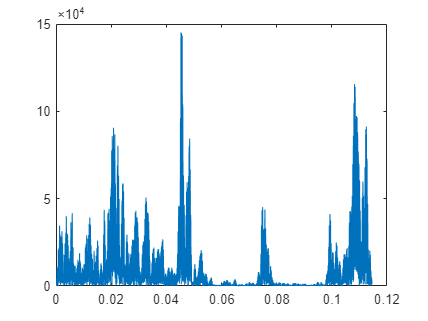

figure(16);
plot(depth3_axis, env3(:,card_cols/2));


env4 = abs(conj(cardRf))*2

env4 = 	1.0e+05 *

    0.0005    0.0067    0.0212    0.0335    0.0194    0.0283    0.0007    0.0090    0.0135    0.0210    0.0037    0.0005    0.0163    0.0231    0.0057    0.0131    0.0065    0.0127    0.0011    0.0088    0.0048    0.0132    0.0074    0.0150    0.0073    0.0140    0.0040    0.0117    0.0026    0.0031    0.0188    0.0124    0.0252    0.0178    0.0367    0.0295    0.0492    0.0431    0.0558    0.0462    0.0875    0.0806    0.0977    0.0900    0.0908    0.0802    0.0879    0.0782    0.0832    0.0771
    0.0129    0.0146    0.0325    0.0388    0.0350    0.0378    0.0249    0.0270    0.0235    0.0247    0.0092    0.0069    0.0198    0.0198    0.0090    0.0094    0.0157    0.0149    0.0027    0.0056    0.0001    0.0018    0.0030    0.0046    0.0015    0.0010    0.0004    0.0013    0.0026    0.0064    0.0209    0.0196    0.0217    0.0199    0.0309    0.0283    0.0385    0.0373    0.0396    0.0345    0.0627    0.0604    0.0693    0.0672    0.0585    0.0541    0.0530    0.0490

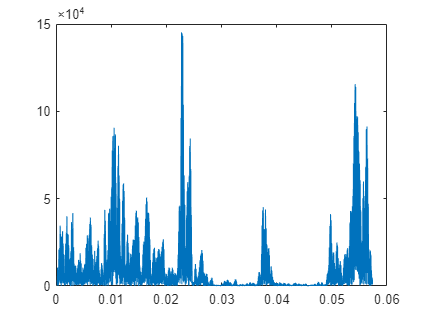

figure(16);
plot(depth4_axis, env4(:,card_cols/2));

Here we need to multiply by 2, to keep the power of the signal.

Task 3

%r1 = Rf1_start_angle:1/Rf1_angle_inc:Rf1_rows/Rf1_angle_inc - 1/Rf1_angle_inc; 
%r2 = Rf2_start_angle:1/Rf2_angle_inc:Rf2_rows/Rf2_angle_inc - 1/Rf2_angle_inc;
theta1 = Rf1_start_angle:1/Rf1_angle_inc:Rf1_cols/Rf1_angle_inc - 1/Rf1_angle_inc; 
theta2 = Rf2_start_angle:1/Rf2_angle_inc:Rf2_cols/Rf2_angle_inc - 1/Rf2_angle_inc; 
theta3 = cardRf_start_angle:1/cardRf_angle_inc:card_cols/cardRf_angle_inc - 1/cardRf_angle_inc; 
cart_image1 = scanconvert(Rf1, depth1_axis,theta1);
cart_image2 = scanconvert(Rf2, depth2_axis,theta2);
cart_image3 = scanconvert(cardRf, depth3_axis,theta3);
cart_image4 = scanconvert(cardRf, depth4_axis,theta3);

gain = -90;
dyn = 60;

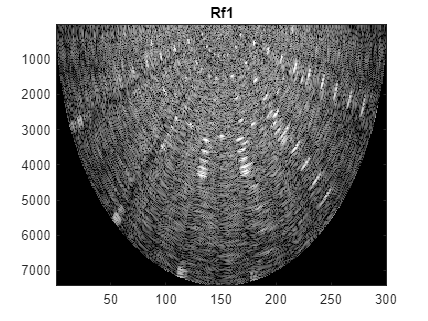

imagesc( 20*log10( abs( cart_image1) ) );
title("Rf1");
caxis([-dyn 0]-gain);
colormap(gray);

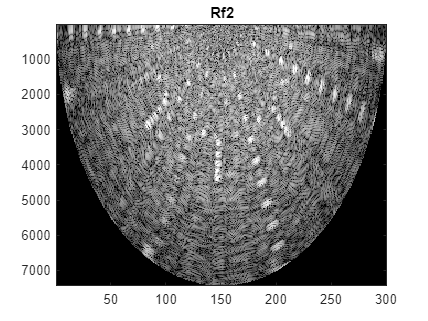



imagesc( 20*log10( abs( cart_image2) ) );
title("Rf2");
colormap(gray);
caxis([-dyn 0]-gain);

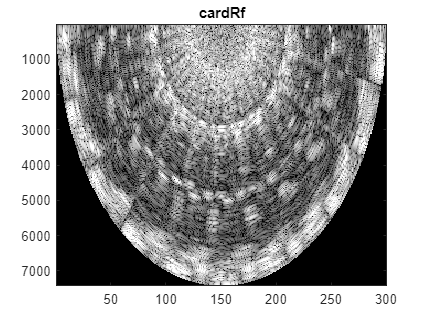

%it seems to be something wrong with my images input since it seems to be
%cut

imagesc( 20*log10( abs( cart_image3) ) );
title("cardRf");
colormap(gray);
caxis([-dyn 0]-gain);

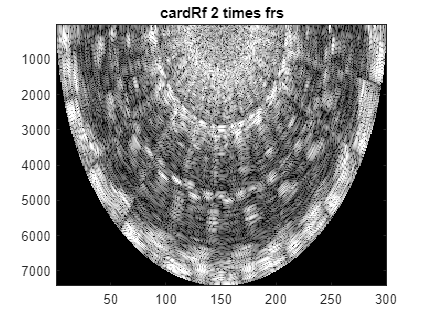


imagesc( 20*log10( abs( cart_image4) ) );
title("cardRf 2 times frs");
colormap(gray);
caxis([-dyn 0]-gain);

The depth seems to have increased from image 1 to image 2

Trying with 2 times fundamental frequency

Seems to lose some contrast with higher frequencies. 

function d = demodulation2(path,fc)
    data = load(path);
    data_rf = data.rf;
    [data_rows,~] = size(data_rf);
    data_f0 = data.p.f0_Hz;
    data_frs = data.p.frs_Hz * 2;
    t = (0:1/data_frs:(data_rows*1/data_frs)-1/data_frs).';
    w = 2*pi*data_f0;
    %window = hamming(length(t));
    %tested with some different freqs 1MHz seems to give the cleanest peak
    [b,a] = butter(6,fc/(data_frs/2));
    d = filter(b,a,data_rf.*exp(-1i*w*t));
    %d = data_rf.*exp(-1i*w*t).*windo;

end
function d = demodulation(path,fc)
    data = load(path);
    data_rf = data.rf;
    [data_rows,~] = size(data_rf);
    data_f0 = data.p.f0_Hz;
    data_frs = data.p.frs_Hz;
    t = (0:1/data_frs:(data_rows*1/data_frs)-1/data_frs).';
    w = 2*pi*data_f0;
    %window = hamming(length(t));
    %tested with some different freqs 1MHz seems to give the cleanest peak
    [b,a] = butter(6,fc/(data_frs/2));
    d = filter(b,a,data_rf.*exp(-1i*w*t));
    %d = data_rf.*exp(-1i*w*t).*windo;

end
